## MATLAB Stiff Problems

In this livescript, you will learn how

- To solve a common class of problems called *stiff problems*.

Consider a linear oscillator that is governed by the following second order differential equation.


$$\frac{d^{2}x}{dt^{2}}+2001\frac{dx}{dt}+2000x=0$$


with the initial conditions $x(0)=1$ and $x'(0)=0$.

(a)        Show that this equation can be written as the following linear system of differential equations


$$\frac{d}{dt}
\pmatrix{
x_{1} \cr
x_{2}
}
=
\pmatrix{
0 & 1 \cr
-2000 & -2001
}
\pmatrix{
x_{1} \cr
x_{2} 
}$$


(b)        Verify that the solution is given by


$$x_{1}(t)=x(t)=\frac{e^{-2000t}(-1+2000e^{1999t})}{1999}\\
x_{2}(t)=x'(t)=2000e^{-t}-\frac{2000 e^{-2000t}(-1+2000e^{1999t})}{1999}$$


To get an idea what this looks like, the following piece of code plots these functions 

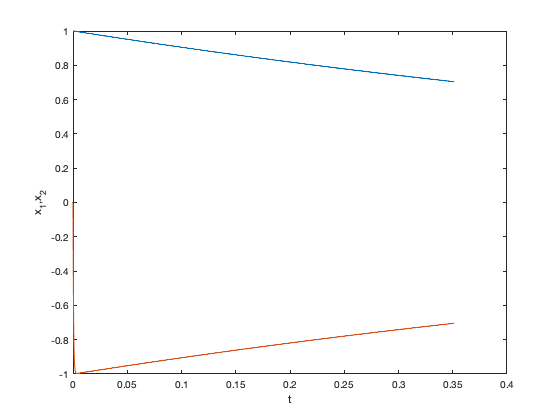

t1 = linspace(0,1,1e5);
x1 = @(t)(exp(-2000*t).*(-1+2000*exp(1999*t)))/1999;
x2 = @(t)(2000*exp(-t)-(2000*exp(-2000*t).*(-1+2000*exp(1999*t)))/(1999));
plot(t1,x1(t1))
hold on
plot(t1,x2(t1))
hold off
xlabel('t')
ylabel('x_{1},x_{2}')

Whereas, if we were to use the explicit Euler method with a step size of $\Delta t= 0.01$ to integrate the equation of motion

f = @odefun;
tspan = [0,0.1];
dt = 0.01;
x0 = [1,0];

t = tspan(1):dt:tspan(2);
x = zeros(length(t),2);
x(1,:) = x0;

for l = 1:length(t)-1
    x(l+1,:) = x(l,:)+dt*f(t(l),x(l,:))';
end

Comparing with the exact solution

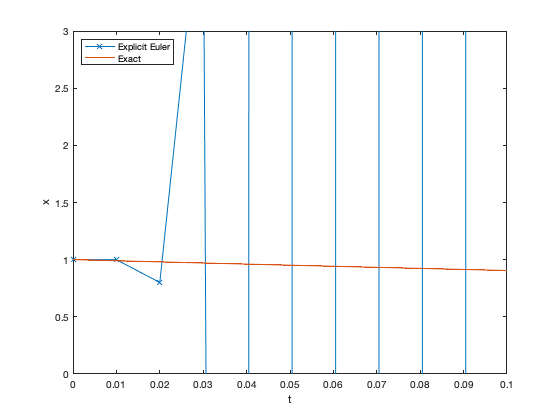

plot(t,x(:,1),'x-')
hold on
plot(t1,x1(t1),'-')
hold off
legend('Explicit Euler','Exact','Location','northwest')
xlabel('t')
ylabel('x')
ylim([0,3])
xlim([0,0.1])

we can see that the solution obtained from the explicit Euler method diverges rapidly, which we call *blow up.*

(c)        Reduce the time step to $h=0.005$ and $h=0.001$ and see if the solution improves.

Following the analysis conducted in Workshop 10, we can subtract the two differential equations and show that the error evolves as


$$\frac{d^{2}e}{dt^{2}}+2001\frac{de}{dt}+2000e=0$$


with the initial conditions $e(0.01)=\epsilon_{1}$ and $e'(0.01)=\epsilon_{2}$, where $\epsilon_{1}$ and $\epsilon_{2}$ are small perturbations to the initial conditions.

We therefore have the following system of differential equations


$$\frac{d}{dt}\{e\}=[A]\{e\}$$


where

$\{e\}
=
\pmatrix{
e_{1} \cr
e_{2}
}
$ and $[A]
=
\pmatrix{
0 & 1 \cr
-2000 & -2001
}$

Recall from Linear Algebra that a matrix $[A]$ can be diagonalised using


$$[\Lambda] = [S]^{-1}[A][S]$$


where $[\Lambda]$ is a diagonal matrix with the entries being given by the eigenvalues


$$[\Lambda]
=
\pmatrix{
\lambda_{1} \cr
& \lambda_{2} \cr
& & \ddots
}$$


and $[S]$ is a transformation matrix where the columns are the eigenvectors. Note that this is provided the eigenvalues are distinct.

Plugging this into the differential equation gives


$$\frac{d}{dt}\{e\}=[S][\Lambda][S]^{-1}\{e\}$$


Or equivalently


$$\frac{d}{dt}[S]^{-1}\{e\}=[\Lambda][S]^{-1}\{e\}$$


If we let 


$$\{z\}=[S]^{-1}\{e\}$$


Then our differential equation becomes


$$\frac{d}{dt}
\pmatrix{
z_{1} \cr
z_{2}
}
=
\pmatrix{
\lambda_{1} & 0 \cr
0 & \lambda_{2}
}
\pmatrix{
z_{1} \cr
z_{2}
}$$


This essentially decouples the differential equations, which means to understand how the error evolves over time, it suffices to just look at the scalar equation 


$$\frac{dz}{dt}=\lambda z$$


Using the results from lectures for the explicit Euler method, these perturbations will be damped out over time if the time step satisfies the inequality


$$|1+\lambda \Delta t|\leq1$$


Since the eigenvalues of the linear oscillator are given by

lambda = eig([0,1;-2000,-2001])

lambda =           -1
       -2000


We can see these are quite large, which means that for a reasonable time step, the previous inequality won't be satisfied.

As the maximum time step for the explicit Euler method is given by


$$\Delta t\leq\frac{2}{|\lambda|}$$


the maximum time step will be given by

max_dt = min(2./abs(lambda))

max_dt = 1.0000e-03

which is what we found before.

Requiring that the step size remains small is one of the defining characteristics of *stiff problems*. 

Therefore, one way they can be defined is if all the eigenvalues are negative and the ratio of the largest eigenvalue in magnitude to the smallest eigenvalue in magnitude is large.

So, to avoid these perturbations to the solution from blowing up, we can either reduce the step size, requiring longer computation times, or we can choose a method with a much larger region of absolute stability.

### Stability of the Implicit Euler Method

Consider the implicit Euler method


$$z_{n+1}=z_{n}+\Delta tf(t_{n+1},z_{n+1})$$


In lectures, it was shown that the stability region is given by


$$|\sigma|=\Big| \frac{1}{1-\lambda \Delta t}\Big|\leq 1$$


(d)        Show that the boundary is defined by the parametric equation


$$\lambda \Delta t=1-e^{-i\theta}$$


for $0\leq\theta\leq 2\pi$.

To plot the boundary, a piece of code is

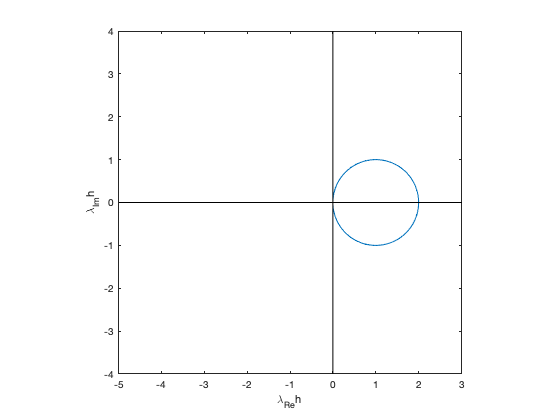

theta = linspace(0,2*pi,100);
s = exp(1i*theta);
lambdah = 1-1./s;
plot(real(lambdah),imag(lambdah))
hold on 
plot([-10,10],[0,0],'k-')
plot([0,0],[-10,10],'k-')
hold off
xlabel('\lambda_{Re}h')
ylabel('\lambda_{Im}h')
xlim([-5,3])
ylim([-4,4])
axis square

(f)        Convince yourselves that the inequality is satisfied if the eigenvalues lie outside the circle.

Therefore, the region of absolute stability includes the entire left half of the complex plane. And if a numerical method has this property, we call it *A-stable*.

So, using the Implicit Euler method to solve the ODE with a time step of $h=0.01$

A = [0,1; -2000,-2001];
tspan = [0,0.35];
h = 0.01;
x0 = [1,0];

t = tspan(1):h:tspan(2);
x3 = zeros(length(t),2);
x3(1,:) = x0;

for l = 1:length(t)-1
    x3(l+1,:) = ((eye(size(A))-h*A)\(x3(l,:)'))';
end

If you wanted to solve these equations using MATLAB, the solvers that are optimised for *stiff problems* have an $\texttt{s}$ after their names such as $\texttt{ode15s}$ and $\texttt{ode23s}$.

[ts,xs] = ode23s(@odefun,[0,1],[1,0]);

Comparing the Implicit Euler method, $\texttt{ode23s}$, and the exact solution gives

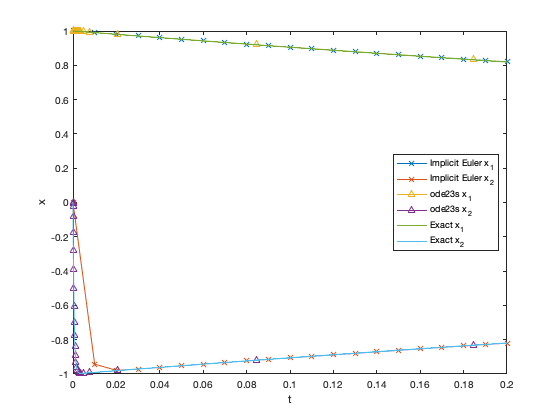

plot(t,x3,'x-')
hold on
plot(ts,xs,'^-')
plot(t1,x1(t1))
plot(t1,x2(t1))
hold off
legend('Implicit Euler x_{1}','Implicit Euler x_{2}','ode23s x_{1}','ode23s x_{2}','Exact x_{1}','Exact x_{2}','Location','east')
xlabel('t')
ylabel('x')
xlim([0,0.2])

Note that while the implicit Euler method is stable, it isn't accurate for small values of $t
$. So be careful not to confuse the two. 

To be clear, stability is about whether small errors/perturbations to the exact solution remain under control (or more precisely bounded) for a given step size. And accuracy is how well the outputs from the numerical method represents the exact solution.

### Nonlinear ODEs

For nonlinear ODEs, the same analysis can be applied if we *linearise* the differential equation.

Consider the general system of differential equations


$$\frac{d}{dt}\{x\}=f(t,\{x\})$$


If we apply the same analysis as before, the error is governed by


$$\frac{d}{dt}\{e\}=f(t,\{x_{a}\})-f(t,\{x\})$$


Expanding $f(t,\{x_{a}\})$ as a Taylor series about $\{x\}$ gives


$$f(t,\{x_{a}\})=f(t,\{x\})+[J](t,\{x\})\{e\}+\mathcal{O}(\{e\}^{2})$$


Hence, to first order we have 


$$\frac{d}{dt}\{e\}=[J](t,\{x\})\{e\}$$


where $[J]$ is the* Jacobi matrix *given by


$$[J]
=
\pmatrix{
\frac{\partial f_{1}}{\partial x_{N}} & \cdots & \frac{\partial f_{1}}{\partial x_{N}}\cr
\vdots & \ddots & \vdots \cr
\frac{\partial f_{N}}{\partial x_{1}} & \cdots & \frac{\partial f_{N}}{\partial x_{N}}
}$$


Be wary that the Jacobi matrix is time dependent, and that in theory a differential equation may have alternating stiff and nonstiff intervals. Therefore, you'll have to look at the physics of the problem to gain further insights.

## Subfunctions

function dxdt = odefun(t,x)
    dxdt = [x(2);
        -2000*x(1)-2001*x(2)];
end